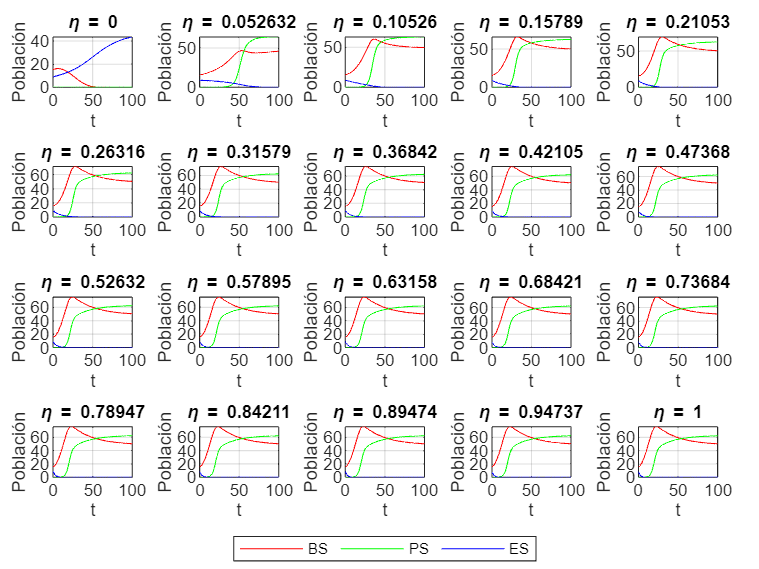

% Limpiar el espacio de trabajo, la ventana de comandos y cerrar figuras
clear;    
clc;     
close all;

% Parámetros fijos
alpha1 = 0.00137; beta1 = 0.07;  gamma1 = 0.01; mu1 = 0.01;
alpha2 = 0.0011;  beta2 = 0.29; gamma2 = 0.01; mu2 = 0.01;
alpha3 = 0.001;   beta3 = 0.1;  tau = 0.0995;  C = 146.9;


% Valores de theta1 y theta2, según la región
region = 1;

if region == 1
    theta1 = 0.0218;
    theta2 = 0.0642;
elseif region == 2
    theta1= 0.083;
    theta2 = 0.0642;
elseif region == 3
    theta1 = 0.25;
    theta2 = 0.0642;
elseif region == 4
    theta1 = 0.6;
    theta2 = 0.0642;
elseif region == 5
    theta1 = 0.0218;
    theta2 = 0.1542;
elseif region == 6
    theta1 = 0.105;
    theta2 = 0.1542;
elseif region == 7
    theta1 = 0.28;
    theta2 = 0.1542;
elseif region == 8
    theta1 = 0.5;
    theta2 = 0.1542;
elseif region == 9
    theta1 = 0.03;
    theta2 = 0.22;
elseif region == 10
    theta1 = 0.033;
    theta2 = 0.268;
elseif region == 11
    theta1 = 0.16;
    theta2 = 0.3;
elseif region == 12
    theta1 = 0.36;
    theta2 = 0.35;
elseif region == 13
    theta1 = 0.5;
    theta2 = 0.35;
elseif region == 14
    theta1 = 0.04;
    theta2 = 0.48;
elseif region == 15
    theta1 = 0.2;
    theta2 = 0.55;
elseif region == 16
    theta1 = 0.25;
    theta2 = 0.46;
elseif region == 17
    theta1 = 0.42;
    theta2 = 0.6;
elseif region == 18
    theta1 = 0.48;
    theta2 = 0.65;
elseif region == 19
    theta1 = 0.05;
    theta2 = 0.8;
elseif region == 20
    theta1 = 0.26;
    theta2 = 0.8;
elseif region == 21
    theta1 = 0.6;
    theta2 = 0.8;
elseif region == 22
    theta1 = 0.8;
    theta2 = 0.8;
end

% Parámetros de tala periódica
T = 2;        % período de tala (2 = año por medio)

% Condiciones iniciales
x0 = [15.4667; 0.0790; 8.9326];
tspan = [0 100];

% Vector de valores de eta
etas = linspace(0, 1, 20); 

figure;
t = tiledlayout(4, 5, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:length(etas)
    eta = etas(i);

    sistema = @(t, x) [
        (alpha1 * x(1) * (C - x(1) - x(2) - x(3))) / (1 + gamma1 * x(3)) ...
            - x(1) * (beta1 + mu1 * x(3) - theta1);
        (alpha2 * x(2) * (C - x(1) - x(2) - x(3)) * (1 + tau * x(1))) / (1 + gamma2 * x(3)) ...
            - x(2) * (beta2 + mu2 * x(3) - theta2);
        alpha3 * x(3) * (C - x(1) - x(2) - x(3)) - beta3 * x(3) -  eta * 0.5 * (1 + cos(2 * pi * t / T)) * x(3);
    ];

    [t_sim, x] = ode45(sistema, tspan, x0);

    nexttile;
    plot(t_sim, x(:,1), 'r'); hold on;
    plot(t_sim, x(:,2), 'g');
    plot(t_sim, x(:,3), 'b');
    title(['\eta = ', num2str(eta)]);
    xlabel('t'); ylabel('Población');
    grid on;
end

% Añadir leyenda global debajo
lgd = legend({'BS', 'PS', 'ES'}, 'Orientation', 'horizontal');
lgd.Layout.Tile = 'south';